#                             SPEECH ENCRYPTION AND DECRYPTION

                                                          THIS IS NOT JUST MODULE 1, THIS IS THE WHOLE PROJECT.

CH.ANVESH ----180020005

K.SRIKAR     ----180020017

**Speech cryptography** is a solution used for transmitting spoken information in a masked way by **encrypting the data at transmitters’ end** and **decrypting at receivers’ end**.The **encryption** is derived by scrambling the original spectrum, and the reverse process is used for **decryption**.

                                     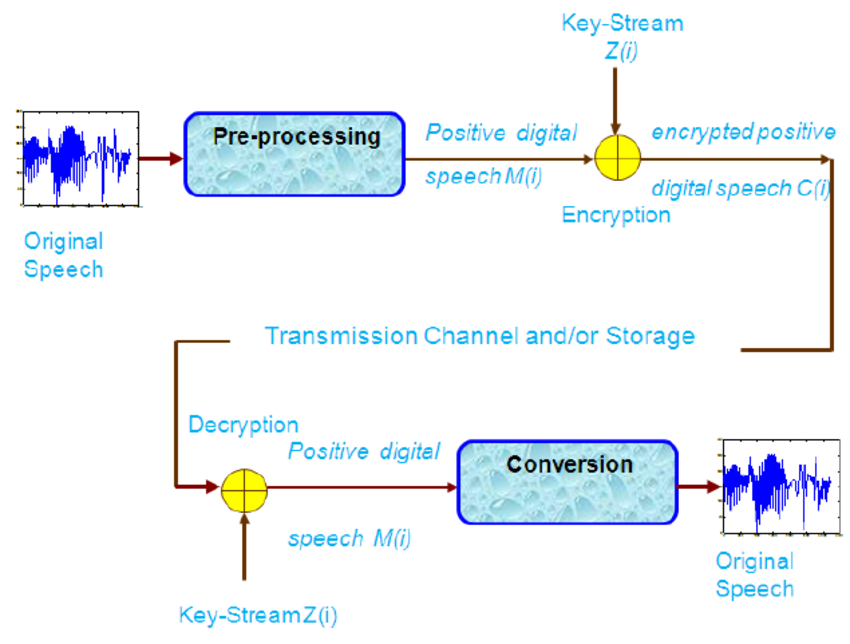

## CRYPTOSYSTEMS:

Fundamentally, cryptosystems can be categorized to two main types based on the way in which encryption and decryption processes are carried out in the cryptosystem: **symmetric key (secret key) cryptosystems** and **asymmetric key (public key) cryptosystems**. In symmetric key cryptosystems, the same key is shared between the transmitter for encryption and the receiver for decryption the data. The strength of symmetric algorithms depends on the size of the secret key. Blowfish, **Advanced Encryption Standard (AES) and Data Encryption Standard (DES) are examples of symmetric key encryption techniques.**

**In asymmetric key cryptosystems**, each user in the system has two different keys: private which is used for encryption at the transmitter and public which is used for decryption at the receiver. Although these two keys are different but they are mathematically related. Thus, reconstructing of the original message by decrypting it is feasible. Asymmetric cipher has several advantages over conventional symmetric ciphers. It means that if the opponent can have both the algorithm of encryption and the public key, he will still need to the private key to decrypt the original message which is available only with the intendent recipient. The disadvantage of this type of encryptions is that they are need more computations than symmetric ciphers. Hence, encryption and decryption processes may take longer time.**RSA is an example of asymmetric key encryption methods.**

**Note:** We will use the **RSA encryption and decryption** method in this Project.

### Audio Signal:

The below code block can be uncommented if the user wants to record his voice.

% recObj = audiorecorder;
% disp('Start speaking.');
% recordblocking(recObj,5);
% disp('End of Recording.');
%data=getaudiodata(recObj);
%audiowrite('saved.wav',data,8000)

" BEFORE  RUNNING  MAKE SURE THAT THE ATTACHED 'sample.wav' AUDIO FILE IS IN THE SAME FOLDER IN WHICH THIS FILE IS PRESENT."

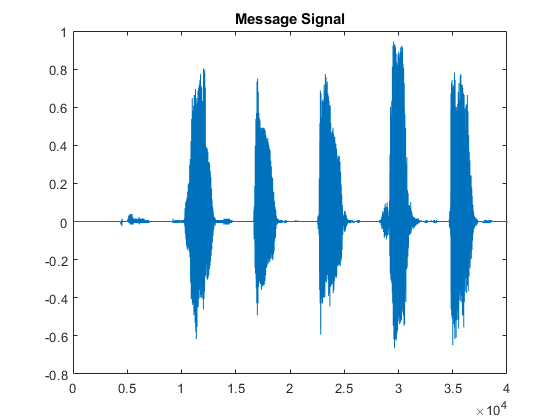

clc;
clear all;

% Read an audio file values into x1. The Sampling Frequency of the audio file is also saved in 'fs'.  
[x,fs] = audioread('sample.wav');
% The audio file 'sample.wav' is a 5 second sample audio.
plot(x);
title('Message Signal')

We will read an audio file and get the values of it to array 'x' and  plot it.

### Signal Pre-Processing:

input_length = length(x); % Finding out the length of the input.
y = fft(x,input_length); % Apllying fft() on input x1. It's length is the length of the input.

 We will apply the **Fast Fourier Transform (FFT)** on the input signal. We will divide the transformed signal 'y' into real and imaginary parts as shown below.

We're treating the real part and imaginary parts seperately and will encrypt and decrypt seperately later after decryption we will make it complex again.

The audio signal which we're using has values between -1 to 1.We are using a precision of 4 decimal places after the decimal point. (Ex : If the signal is like 0.123456 we will make it 0.1234).

% The fft signal y is divided into real and imaginary parts. 
y_real = real(y);% real part of fft of speech
y_imag = imag(y);% imaginary part of fft of speech
y_real = floor(y_real*10000);% Rounding upto 4 decimal places
y_imag = floor(y_imag*10000);% Rounding upto 4 decimal places

We will convert the signal into binary.We will have sign bit as MSB. If the signal is -ve the sign bit is '1' and vice versa. So here there is a question how we will convert decimal values ? What we're going to do is to make it integer we're going to scale up the signal by the precision we desire. Basically in the previous example of 0.1234 we will convert it to 1234 and convert to binary and later in decryption we will scale it down to make it 0.1234. A decimal number like 6 can have a binary form '110' with 3 bits and '000110' with 6 bits .So to maintain equal no.of bits for every signal we will find the maximum value of signal and found the no.of bits required for that and maintain the same no.of bits for each value of signal.  

THE FOLLOWING CODE BLOCK DOES THE ABOVE EPLAINED.

max_real = max(abs(y_real));% max of real values
max_imag = max(abs(y_imag));% max of imaginary values
maxim=max(max_real,max_imag);% max of all values
num_bits = floor(log2(maxim))+1; % no.of bits required 

In the following block we will convert decimal form of our signal into a binary string and concatenate each value to the before string so will have a big string of binary. We will convert each signal to binary with no.of bits found above and a sign bit as MSB so our binary signal length for each is (num_bits+1) 

binary_string_real = ' '; % initialising binary string
binary_string_imag = ' ';
for i = 1:input_length
    % Real part.
    if y_real(i) < 0      % adding a sign bit
        binary_string_real = strcat(binary_string_real,'1');
    else 
        binary_string_real = strcat(binary_string_real,'0');
    end
    
    %converting decimal signal to binary string.
    temp_real_in = dec2bin(abs(y_real(i)),num_bits);
    
    % concatenating each string to make it big string of binary values.
    binary_string_real = strcat(binary_string_real,temp_real_in);
    
    %  Doing the same for imaginary part.
    if y_imag(i) < 0
        binary_string_imag = strcat(binary_string_imag,'1');
    else 
        binary_string_imag = strcat(binary_string_imag,'0');
    end
    
    temp_imag_in = dec2bin(abs(y_imag(i)),num_bits);
    binary_string_imag = strcat(binary_string_imag,temp_imag_in);
end

## RSA:

**RSA** is basically an authentication system and Internet encryption method. This algorithm was developed by its inventors in 1977 (Ron** Rivest, **Adi** Shamir **and Leonard** Adleman**).Initially, two large prime numbers are chosen and multiplied in this algorithm to create the **public and the private keys** pair which are further used in the encryption and decryption operations. The private key is utilized to decrypt the secret message at the receiver which has been ciphered or encrypted by using the public key at the transmitter. Everyone can know the public key which is used to encrypt the messages, but the encrypted messages by the public key can be decrypted only with the private key. Three steps are involved in RSA which are** key generation, encryption and decryption processes.**

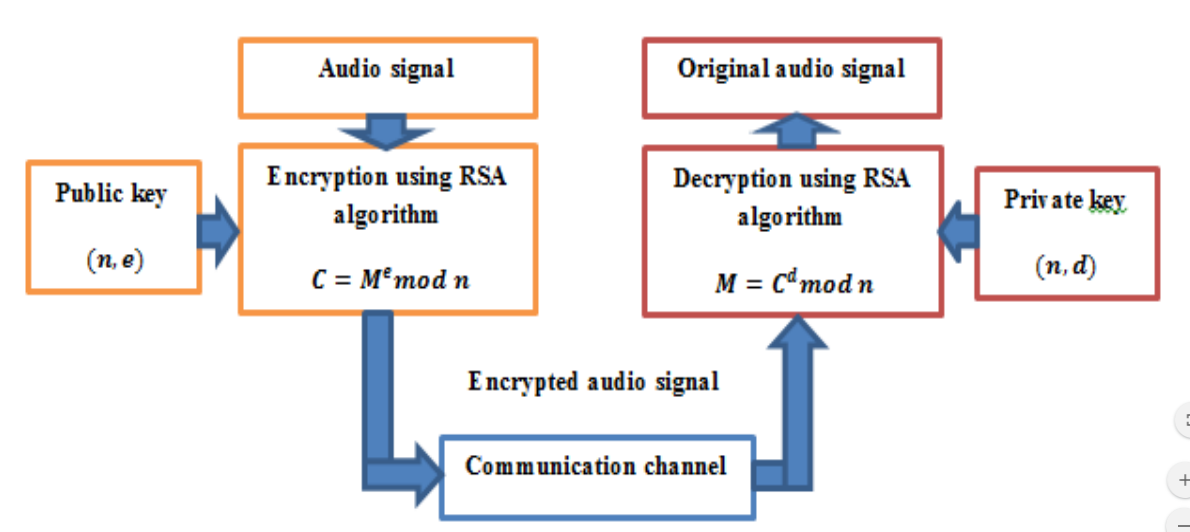

### Key generation:

The following steps illustrate the key generation in RSA algorithm: 

-  Choose two prime integers 𝑝 and 𝑞. The modulus 𝑛 can be computed from these two numbers, 𝑛 = 𝑝 ∗ 𝑞. 

-  Calculate Euler’s totient function ∅ 𝑓𝑜𝑟 𝑛 from the equation: ∅(𝑛) = (𝑝 − 1)(𝑞 − 1). 

-  Choose a third integer number 𝑒 such that gcd (∅(𝑛),𝑒) = 1. i.e. ∅(𝑛) 𝑎𝑛𝑑 𝑒 are coprime, where 𝑒 represents the public exponent. 

-  Compute an integer number 𝑑 using the formula 𝑑 = 𝑒 −1𝑚𝑜𝑑 ∅(𝑛), where 𝑑 represents the private exponent. 

-  RSA is applicable only on integers so that's why are converting to binary and then to integers.

The number pair (𝑛,𝑒) which represents the modulus and the encryption or public exponent is referred to the public key while the number pair (𝑛, 𝑑) which represents the modulus and the decryption or private exponent that should be kept secret is referred to the private key. 𝑝, 𝑞 𝑎𝑛𝑑 ∅(𝑛) have to be kept secret because these parameters may be utilized to compute 𝑑.

% Key generation
p = 5; % Prime no. p
q = 7; % Prime no. q
n = p*q; % Product of Prime no.'s = n.
phi_n = (q - 1)*(p - 1); % Euler's totient Function for n.

% For loop to find out e. 
for j = 2:(phi_n - 1)
    if gcd(phi_n,j) == 1
        break
    end
end

% 1 < e < phi(n) where e,n are co-primes.
e = j; % Public key variable 'e'.
d = 0; % Private key variable 'd'.
rem = 0; % Remainder variable 'rem'.

% Loop to find out d.
while rem ~= 1
    d = d + 1;
    rem = mod((e*d),phi_n);
end

### Encryption Process: 

The public key (𝑛,𝑒) is used to encrypt the plain message 𝑀 at the transmitter to produce the cipher message 𝐶 by using the formula

                                                                            
$$C = M^e mod (n)$$


 Then, this ciphered or encrypted message 𝐶 is transmitted to the intended receiver. 

But the RSA encryption technique that we're going tp use has some practical set backs to deal with.

The RSA process by design we have to use large prime numbers p and q. But if we use large p and q the values od e and d will be large. And if we do M^e it will be a large value and matlab treats it as infinte value and returns  'NaN'. So we're going to take four bits at a time from the binary string and apply RSA for it. If we take four bits at a time the values will be in range 0-15 and our prime numbers are small so our rsa values won't go up to infinte. We're taking 4 bits at a time so the binary string should be of length divisible by four if not we will pad with zeros to make it divisible by 4.

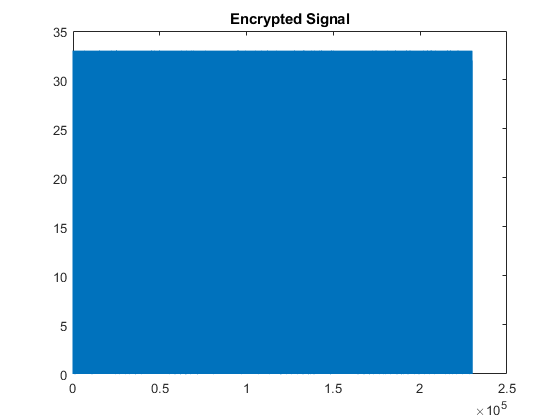

len_bin = strlength(binary_string_real);% Length of binary string 
zero_pad = mod(len_bin,4); % no.of zeros to be padded to make it divisible by 4 


% --------------------- ZERO PADDING---------------------
if zero_pad ~= 0
    for pad = 1:(4 - zero_pad)
         binary_string_real = strcat(binary_string_real,'0');
         binary_string_imag = strcat(binary_string_imag,'0');
    end
end



% ------------------ENCRYPTION---------------------------

len_bin = strlength(binary_string_real);
encrypted_real = zeros(len_bin/4,1); % initialising encrypted array for real values
encrypted_imag = zeros(len_bin/4,1); % initialising encrypted array for imaginary values

% Real part.
for ind = 1:(len_bin/4)
     temp_bin_re = binary_string_real((4*ind - 3):4*ind); % taking 4 bits at a time
     temp_dec_re = bin2dec(temp_bin_re); % coverting those 4 bits to decimal
     encrypted_real(ind) = mod(temp_dec_re^e,n); % applying rsa for that
     % similarly for imaginary part
     temp_bin_im = binary_string_imag((4*ind - 3):4*ind);
     temp_dec_im = bin2dec(temp_bin_im);
     encrypted_imag(ind) = mod(temp_dec_im^e,n);
end
figure;
plot(encrypted_real);
title('Encrypted Signal')

###                        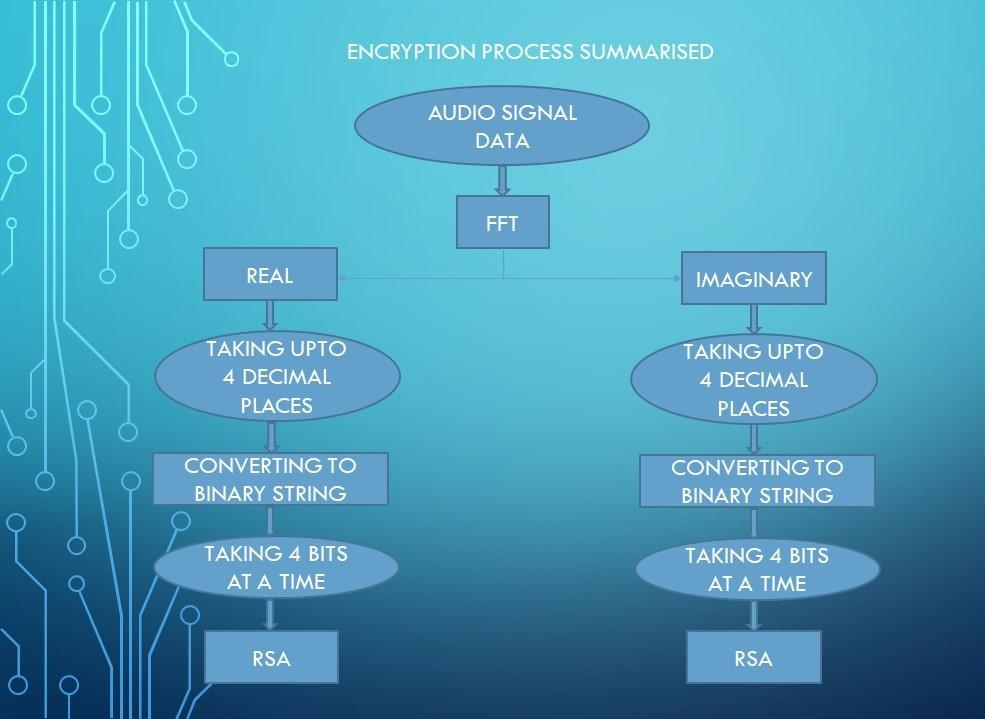

### Decryption Process:

 The private key (𝑛, 𝑑) is used to decrypt the ciphered message 𝐶 at the receiver to produce the plain message 𝑀 by using the formula 

                                                                                
$$M = C^d mod (n)$$


decrypted_real = zeros(len_bin/4,1);
decrypted_imag = zeros(len_bin/4,1);
de_binary_real = ' ';
de_binary_imag = ' ';


for de_ind = 1:length(encrypted_real)
     temp_de_re = mod(encrypted_real(de_ind)^d,n); % rsa decryption technique
     temp_de_bin_re = dec2bin(temp_de_re,4); % converting it to binary string
     de_binary_real = strcat(de_binary_real,temp_de_bin_re); % conactenating it to make a big binary string
     temp_de_im = mod(encrypted_imag(de_ind)^d,n);
     temp_de_bin_im = dec2bin(temp_de_im,4);
     de_binary_imag = strcat(de_binary_imag,temp_de_bin_im);
end



In the below block we're going to convert the big binary string in to decimal signal by considering no.of bits that we found above i.e, 'num_bits'.

de_len = strlength(de_binary_real);
output_real = zeros(floor(de_len/(num_bits+1)),1);% initialising output array for real values
output_imag = zeros(floor(de_len/(num_bits+1)),1);% initialising output array for imaginary values


for t = 1:de_len/(num_bits+1)
    temp_out_real = de_binary_real(((num_bits+1)*(t-1)+2):(num_bits+1)*t);
    output_real(t) = bin2dec(temp_out_real);
    if de_binary_real((num_bits+1)*(t-1)+1) == '1' % finding sign bit  and making +ve or -ve
        output_real(t) = (-1)*output_real(t);
    end
    % similarly for imaginary values
    temp_out_imag = de_binary_imag(((num_bits+1)*(t-1)+2):(num_bits+1)*t);
    output_imag(t) = bin2dec(temp_out_imag);
    if de_binary_imag((num_bits+1)*(t-1)+1) == '1'
        output_imag(t) = (-1)*output_imag(t);
    end
end


##        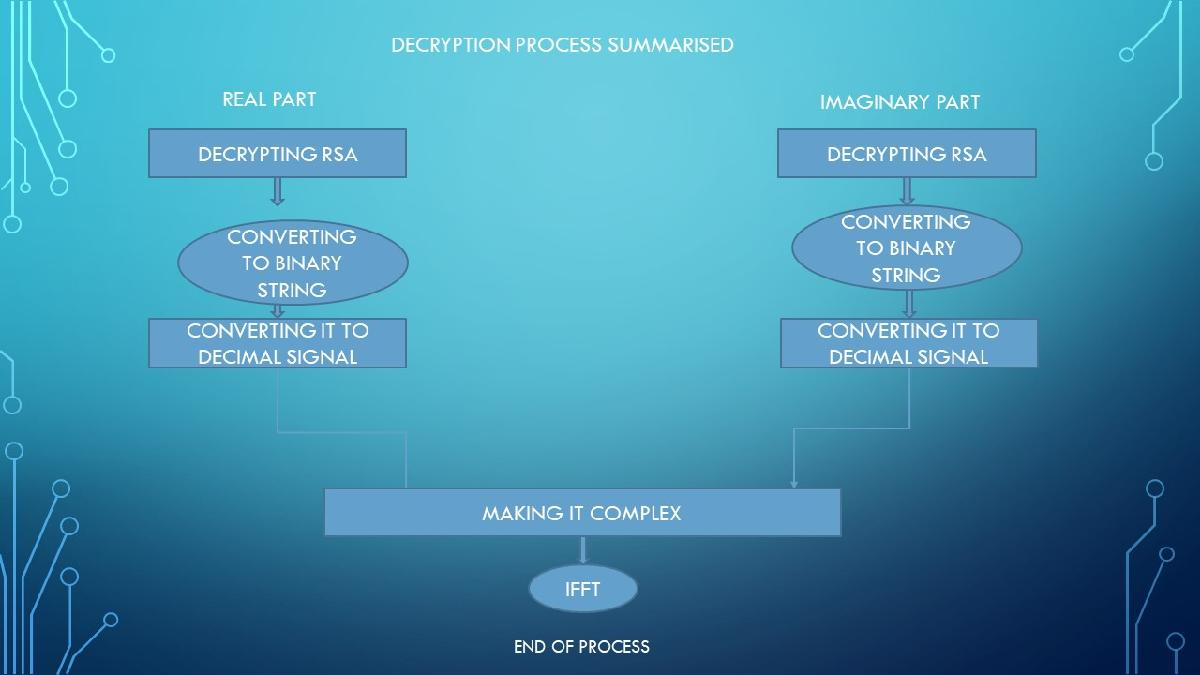

## OUTPUT : 

For the final output we're going to add the real part and imaginary part and scale it down as we have initially scaled it up.

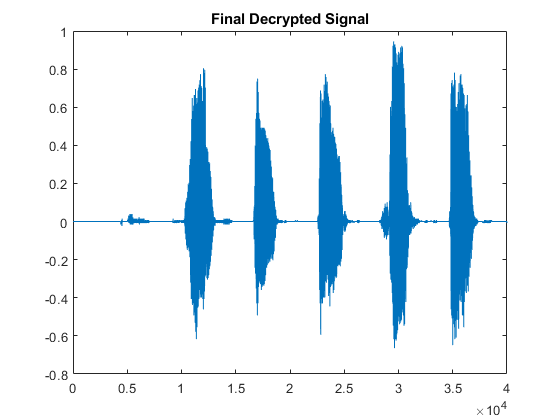

output = (output_real+1i*output_imag)/10000;% making complex signal
final_output = ifft(output,input_length);% finding the ifft to get back the message signal 
y_out = real(final_output);
sound(y_out,fs)
audiowrite('outputaudio.wav',y_out,8000) % writing it to a file
figure;
plot(y_out);
title('Final Decrypted Signal');

You can play the input audio i.e, 'sample.wav' and final output audio file i.e, 'outputaudio.wav' to compare them. Both are '.wav' files so windows media player can play it.

IS THE SIGNAL ENCRYPTION GOOD ENOUGH??

-  We are not directly using the message signal and encrypting that, instead we're using FFT of that and applying RSA technique on both real and imaginary values.

- Even after applying the  FFT  we're not encrypting that, rather we're converting it to a digital signal and taking 4 bits at a time and applying RSA on that .

So by considering above two points we can say that the signal encryption is strong enough that it cannot be decrypted easily.  

##                                                                     THANK YOU!